s=tf('s');
G=zpk(2/(s*(s+1)*(s+4)))


G =
 
        2
  -------------
  s (s+4) (s+1)
 
Continuous-time zero/pole/gain model.



FT=feedback(G,1)


FT =
 
                  2
  ----------------------------------
  (s+4.153) (s^2 + 0.8472s + 0.4816)
 
Continuous-time zero/pole/gain model.



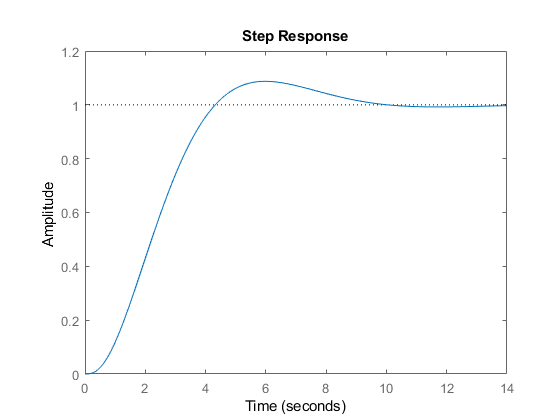

step(FT)

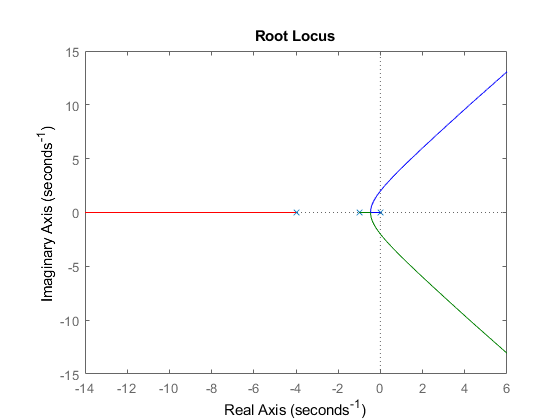

rlocus(G)

stepinfo(FT)

ans = struct with fields:
        RiseTime: 2.7588
    SettlingTime: 8.8432
     SettlingMin: 0.9025
     SettlingMax: 1.0874
       Overshoot: 8.7419
      Undershoot: 0
            Peak: 1.0874
        PeakTime: 5.9790


mp=0.05

mp = 0.0500

ts=3;
zeta=-log(mp)/(sqrt(pi^2+log(mp)^2))

zeta = 0.6901

Wn=4/(zeta*ts);
M=tf(Wn^2,[1 2*zeta*Wn Wn^2])


M =
 
          3.733
  ---------------------
  s^2 + 2.667 s + 3.733
 
Continuous-time transfer function.



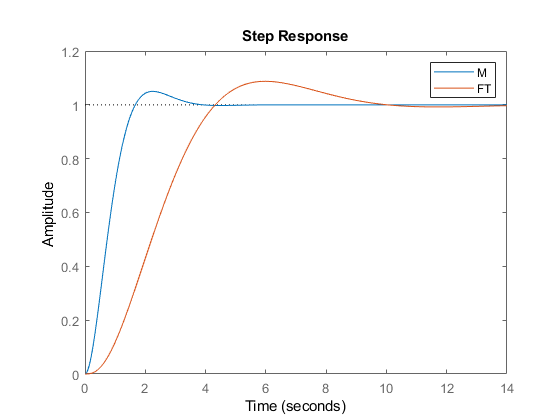

step(M,FT),legend